# **ACTIVIDAD 1.10. SLAM de Lidar**

**Jesús Alejandro Gómez Bautista | A01736171**

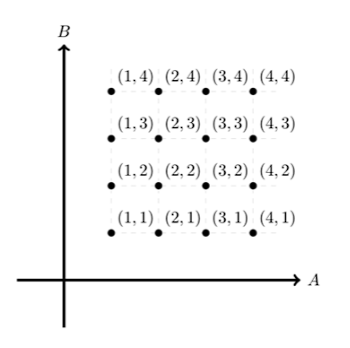

**EXAMPLE MAP**

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.01;              % Sample time [s]
tVec = 0:sampleTime:120;        % Time array

% Initial conditions
initPose = [2.7;2;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap.mat

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51
lidar.maxRange = 1.2;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
             2.7 2;
             2.7 5;
             2.7 8;
             5.7 11;
             2.7 11;
             5.7 8;
             8.7 11;
             11.7 11;
             11.7 8;
             8.7 8;
             11.7 5;
             8.7 5;
             5.7 5;
             11.7 2;
             8.7 2;
             5.7 2];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.5;%0.5
controller.DesiredLinearVelocity = 0.5; %0.75
controller.MaxAngularVelocity = 60

controller =   controllerPurePursuit with properties:

                Waypoints: [17×2 double]
       MaxAngularVelocity: 60
        LookaheadDistance: 0.5000
    DesiredLinearVelocity: 0.5000


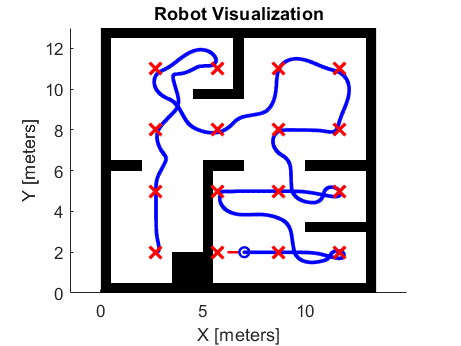


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

Dado los puntos sugeridos en el mapa, al ubicarse únicamente entre los primeros 4 rangos en x y en y, decidí ajustarlo a las dimensiones del mapa de forma que estos puntos coincidieran en algún punto de la región de movimiento (zona blanca del mapa) sin colisionar con alguna región restringida (trazos negros del mapa), por lo que partiríamos en x desde 2.7 e incrementaríamos 3 unidades entre punto desde x, mientras que en y a partir de 2 pero con el mismo incremento de 3 unidades.  

Para lograr la ruta sin colisiones fue necesario ajustar el orden de los puntos, presentando especial dificultad en aquellas zonas donde las líneas de restricción coincidían de forma perpendicular, por lo que se optó por intentar restringir estas rutas para no atravesar un muro, de igual forma, dada la sensibilidad del Lidar, se presentó cierta dificultad en los puntos cercanos a la pared, por lo que se optó por ajustar la ruta para llegar a ellos.

**COMPLEX MAP**

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.01;              % Sample time [s]
tVec = 0:sampleTime:240;        % Time array

% Initial conditions
initPose = [6;18.5;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load complexMap.mat

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,100);%51
lidar.maxRange = 0.6;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)';
             6 18.5;
             10 14;
             6 14;
             14 14;
             18 18.5;
             14 14;
             14 18.5;
             10 18.5;
             14 14;
             18 14;
             21 12;
             18 9.5;
             14 5;
             18 5;
             14 5;
             10 9.5;
             14 9.5;
             14 5;
             6 5;
             10 5;
             6 9.5];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 1;%0.5
controller.DesiredLinearVelocity = 0.5; %0.75
controller.MaxAngularVelocity = 60

controller =   controllerPurePursuit with properties:

                Waypoints: [22×2 double]
       MaxAngularVelocity: 60
        LookaheadDistance: 1
    DesiredLinearVelocity: 0.5000


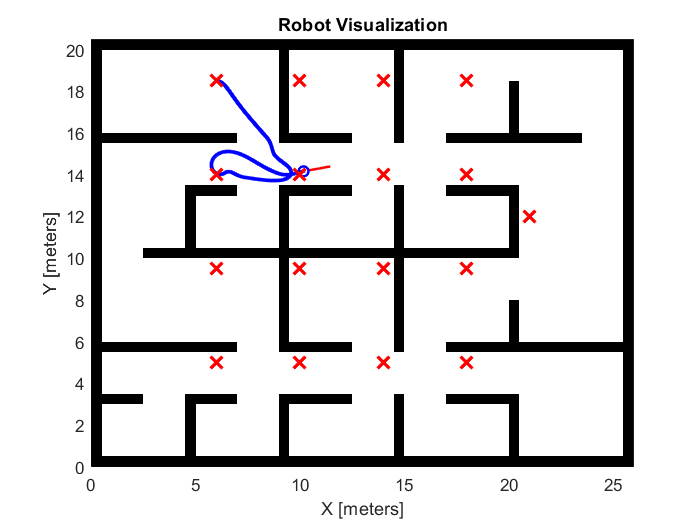


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L;
vfh.SafetyDistance = L;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 0.5*steerDir;
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

Similar a lo que pasa en el paso anterior,  se decidió ajustar a las dimensiones del mapa de forma que estos puntos coincidieran en algún punto de la región de movimiento (zona blanca del mapa) sin colisionar con alguna región restringida (trazos negros del mapa), por lo que partiríamos en x desde 6 e incrementaríamos 4 unidades entre punto desde x, mientras que en y a partir de 5 pero con incrementos de 4.5.

Este resultó más retador que el anterior, partiendo del mismo problema, el de la incapacidad de detección de objetos en paralelo, se ajustó el recorrido en un primer lugar a recorrer una única vez todos los puntos, sin embargo, esto generó que en más de una ocasión se atravesaran los muros. Por lo anterior, se decidió que en ciertas zonas (particularmente las zonas que asemejaban  un cuadrado) se pasará por un mismo punto para entrar y para salir, adicionalmente, se agregó un Landmark adicional por las coordenadas (21, 12) con el fin de pasar de la zona superior a la inferior sin atravesar los muros.